li=-2;
ls=1;
fplot(f,[li,ls])

yline(0,'r','linewidth',1)
xs=li:0.0001:ls;
n=length(xs)

n = 30001

rgs=[]; %%%Regiones 
t=0;

for i=2:n
 if f(xs(i))==0
 t=t+1;
 rgs(t,1)=rango(i-1);
 rgs(t,2)=rango(i+1);
 end
 if (f(xs(i))*f(xs(i+1)))<0
 t=t+1;
 rgs(t,1)=xs(i);
 rgs(t,2)=xs(i+1);
 end
end
rgs

rgs =    -1.9316   -1.9315
   -1.0494   -1.0493


hold on
grid on
[r,~]=size(rgs)

r = 2

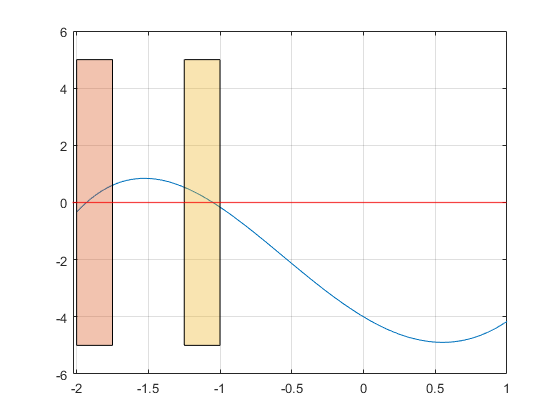

for i=1:r
 plot(polyshape([rangos(i,1) -5;rangos(i,2) -5;rangos(i,2) 5;rangos(i,1) 5]))
end
hold off